%Matlab-Studentenlösung von Benjamin Rauwolf für Machine Learning und Big Data
%zur besseren Durcsuchung aller Seiten der Spiegelkategorie "Fahrberichte"
%
%Init
clear();
close all;
tic;

%get landing page html
headurl = "https://www.spiegel.de/auto/fahrberichte/p1/";
fullhead = webread(headurl);
tree = htmlTree(fullhead);

%get pages
pagecount = str2double(cell2mat(erase(extractBetween(fullhead,'Seite 1','</div>'),'/')));
clear("fullhead");

%get html of all pages
attr = "href";
selector = "A";
for i=1:pagecount(1,1)
    headurl = "https://www.spiegel.de/auto/fahrberichte/p"+i+"/";
    fullhead = webread(headurl);
    tree = htmlTree(fullhead);
    clear("fullhead");

    subtrees = findElement(tree,selector);
    strurls = getAttribute(subtrees,attr);
    clear("subtrees","tree");

    idx = contains(strurls,"https://www.spiegel.de/auto/fahrberichte/");
    closeurls = strurls(idx,1);
    closeurls = sortrows(closeurls,1,"ascend");
    actualurls = unique(closeurls,'rows');
    actualurls(1:2,:) = [];
    if i==1
        allurls = actualurls;
    else
        allurls = [allurls;actualurls];
    end
    clear("headurl","strurls","idx","closeurls","actualurls");
end
allurls = sortrows(allurls,1,"ascend");
clear("pagecount","i","attr","selector");

%Get Keywords
options = weboptions;
options.Timeout = 30;  %Set Timeout-Time to Infinite or to a real time based on your internet connection
%es wird vorausgesetzt, dass es maximal 20 Keywords je Artikel gibt (bisher
%wurden nie mehr als 12 festgestellt)
vartypes = "string";
vartypes = repmat(vartypes,1,20);   %Ein Maximum an 20 Keywords je Artikel wird angenommen (bisher max. 12)
keys = table('Size',[height(allurls) 20],'VariableTypes',vartypes);
for i=1:height(allurls)
    url = allurls(i,1);
    try   %Timeout Catch to skip non working connections
        fullhtml = webread(url);
    catch
        warning("Timeout");
        continue
    end
    tree = htmlTree(fullhtml);
    raw = tree.string;
    str = extractBetween(raw,'name="news_keywords" content="','"/>');
    str = split(str,', ')';
    unistr = unique(str);
    keys(i,1:length(unistr)) = array2table(unistr);

    [nodenames, ~, ~] = unique(str(:));
    strent = "string";
    strent = repmat(strent,1,numel(nodenames)+1);
    adj = table('Size',[numel(nodenames), numel(nodenames)+1],'VariableTypes',strent);
    for zeta=1:length(nodenames)
        adj(zeta,2:end) = array2table(nodenames');
    end
    adj(:,1) = array2table(nodenames);
    for omicron=2:width(adj)
        adj.(omicron){omicron-1} = '';
    end
    for yota=2:width(adj)
        for gamma=1:height(adj)
            if table2array(adj(gamma,yota))==""
                adj(gamma,yota:end-1) = adj(gamma,yota+1:end);
            end
        end
    end
    adj(:,end) = [];
    %adj_list = writematrix(adj,'Delimiter',',','WriteMode','append');
    writetable(adj,'adj_matlab.csv','WriteMode','append');
    if i==1
        writetable(adj,'adj_matlab.csv','WriteMode','overwrite');
    end
    clearvars -except allurls keys;
end
adj_list = readtable("adj_matlab.csv");
adj_list = sortrows(adj_list);          
writetable(adj_list,'adj_matlab.csv','WriteMode','overwrite');
clearvars -except keys;

%modify table
keysarray = table2array(keys);
keys1Darray = keysarray(:);
onlywords = rmmissing(keys1Darray);
clear("keysarray","keys","keys1Darray");

%count keywords
[GC,GN] = groupcounts(onlywords);
tabelle = table(GN,GC,'VariableNames',["Keywords" "Haeufigkeit"]);
tabelleSorted = sortrows(tabelle,2,"descend");
toc     %Zeitmessung

Elapsed time is 1961.973139 seconds.



writetable(tabelleSorted,"TabelleSorted.csv");
% writematrix(GN,"uniquewords.txt");
clear("GC","GN","onlywords");

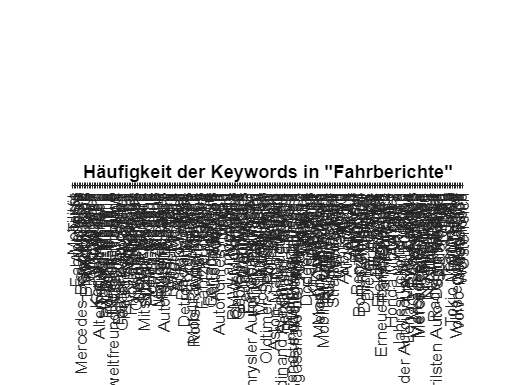

%Darstellung
X = categorical(tabelleSorted.Keywords);
X = reordercats(X,tabelleSorted.Keywords);
Y = tabelleSorted.Haeufigkeit;
bar(X,Y)
title('Häufigkeit der Keywords in "Fahrberichte"')
ylabel("Häufigkeit");

%xlabel("Keywords");
clear("tabelleSorted","tabelle","X","Y")